9주차 MATLAB 과제

(1)

clc, clear; clf;

x = 0:0.05:6*pi;
y = sin(x) + 0.5*cos(3*x);
disp("9-1")

9-1


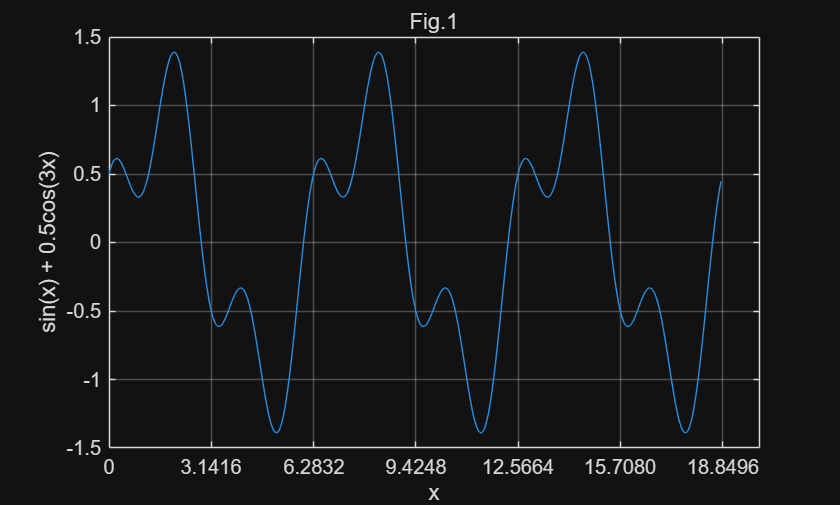

plot(x,y);
xticks(0:pi:6*pi);
grid on
xlabel("x");
ylabel("sin(x) + 0.5cos(3x)");
title("Fig.1");

(2)

clc; clear; clf;

x = 1:1:50;
y = 3.^x;
disp("9-2");

9-2


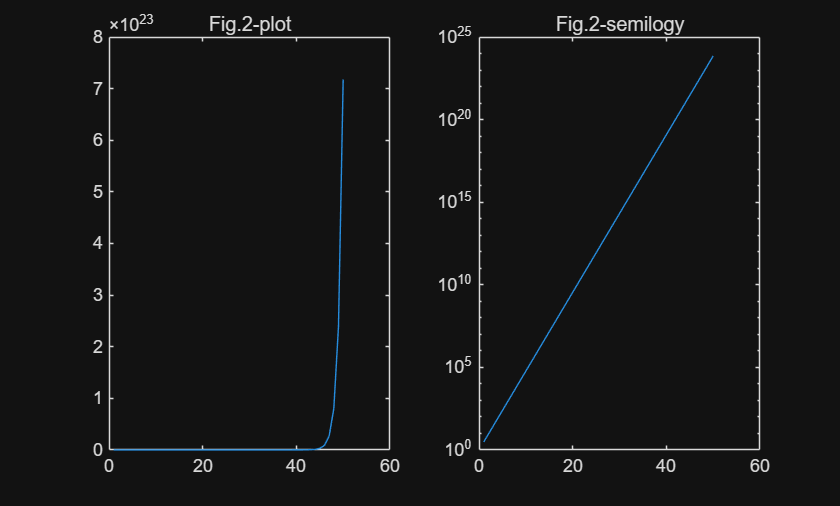

subplot(1,2,1); plot(x,y);
title("Fig.2-plot");
subplot(1,2,2); semilogy(x,y);
title("Fig.2-semilogy");

 Fig.2-1plot은 x축의 값이 오름에 따라 기하급수적으로 숫자가 상승하여 x가 비교적 작은 부분의 그래프는 알아보기 힘들다. 반면, Fig.2-2semilogy는 y축이 log비율로 나누어져있어 알아보기 쉬운 선형의 형태를 띤다.

(3)

clc; clear; clf;

score = load('score.dat');

disp("9-3")

9-3


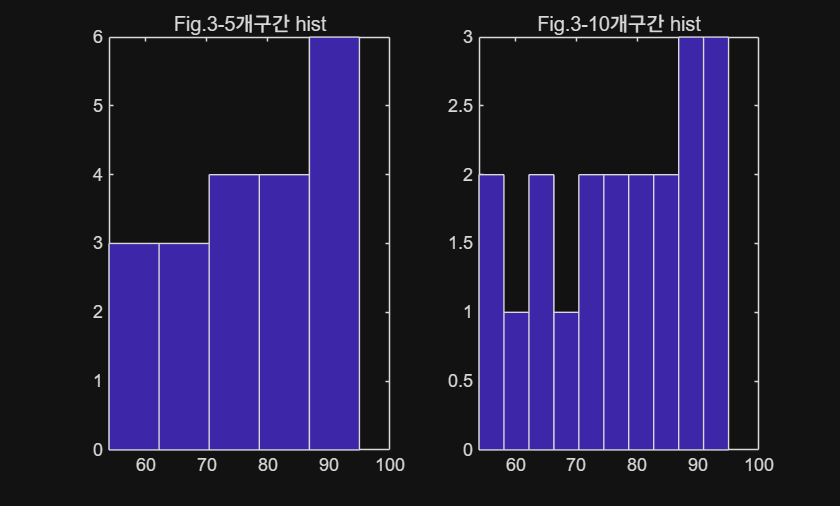

subplot(1,2,1);
hist(score, 5);
title("Fig.3-5개구간 hist");
subplot(1,2,2);
hist(score, 10);
title("Fig.3-10개구간 hist");

(4)

clc; clear; clf;

subplot(1,1,1);
f = @(x) sin(x) .* exp(-0.1.*x);
disp("9-4");

9-4


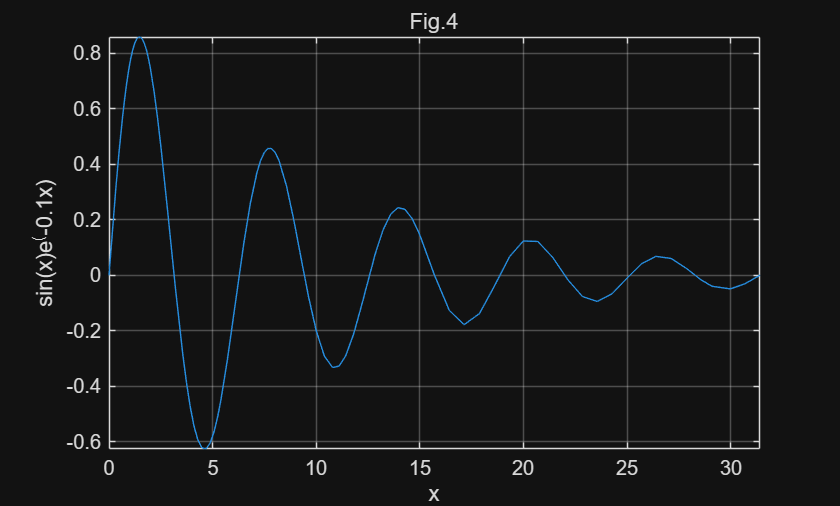

fplot(f, [0, 10*pi])
title("Fig.4");
xlabel('x');
ylabel("sin(x)e^(-0.1x)");
grid on

(5)

clc; clear; clf;

x = 0:0.1:10;
y1 = x.^2;
y2 = exp(0.5.*x);
disp("9-5");

9-5


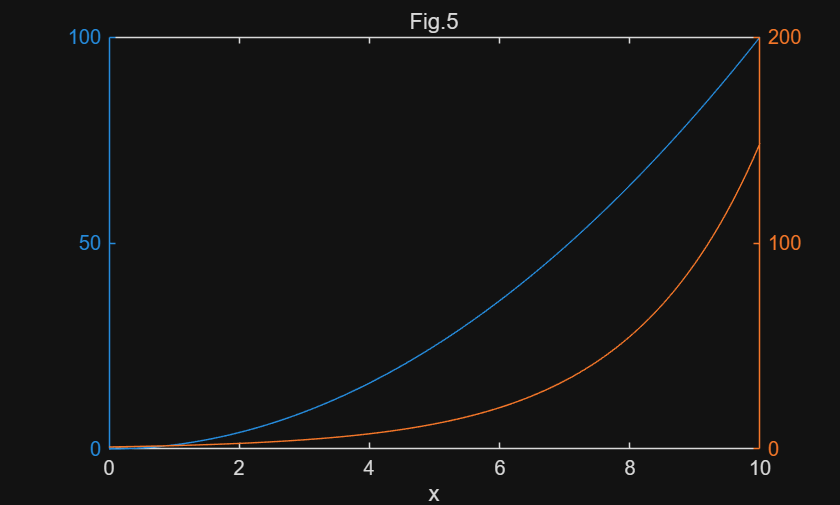

plotyy(x,y1,x,y2);
title("Fig.5");
xlabel("x");

 y1은 y2보다 전반적으로 기울기 변화의 변화가 적다. 반면, y2는 y1보다 기울기 변화가 가파르게 상승한다.

(6)

clc; clear; clf;

disp("9-6");

9-6


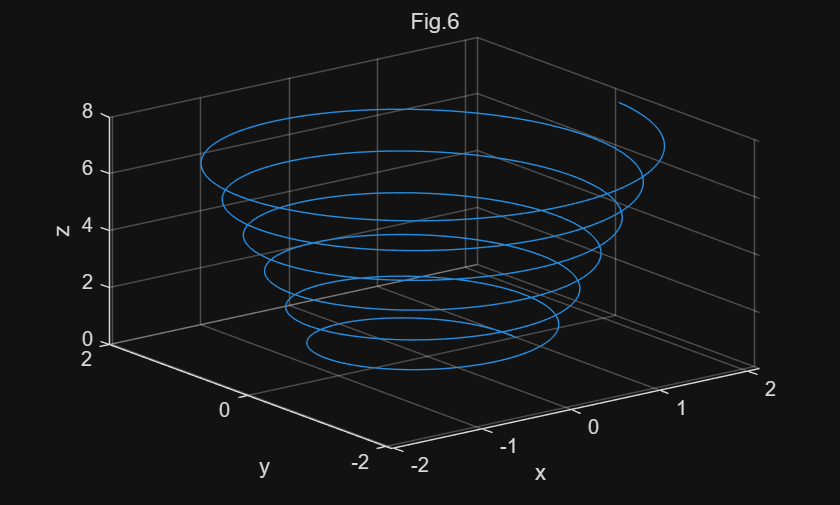

subplot(1,1,1);
t = 0:0.02:12*pi;
x = (1 + 0.03.*t) .* cos(t);
y = (1 + 0.03.*t) .* sin(t);
z = 0.2.*t;

plot3(x,y,z);
title("Fig.6");
xlabel("x");
ylabel("y");
zlabel("z");
grid on;

(7)

clc; clear; clf;
[x, y] = meshgrid(-4:4);
z = x.^2 - y.^2;

disp("9-7");

9-7


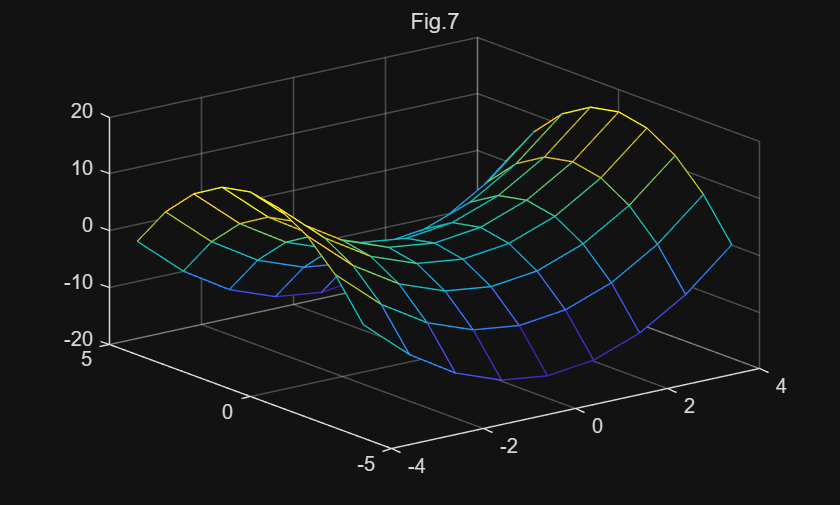

mesh(x, y, z);
title("Fig.7");

 Fig.9-7은  x=y=0일 때, x가 최대값이며, y가 최솟값인 안장점을 가지는 saddle surface이다.

(8)

clc; clear; clf;

[x, y] = meshgrid(-2*pi:0.5:2*pi);
z = sin(x).*cos(y);

disp("9-8");

9-8


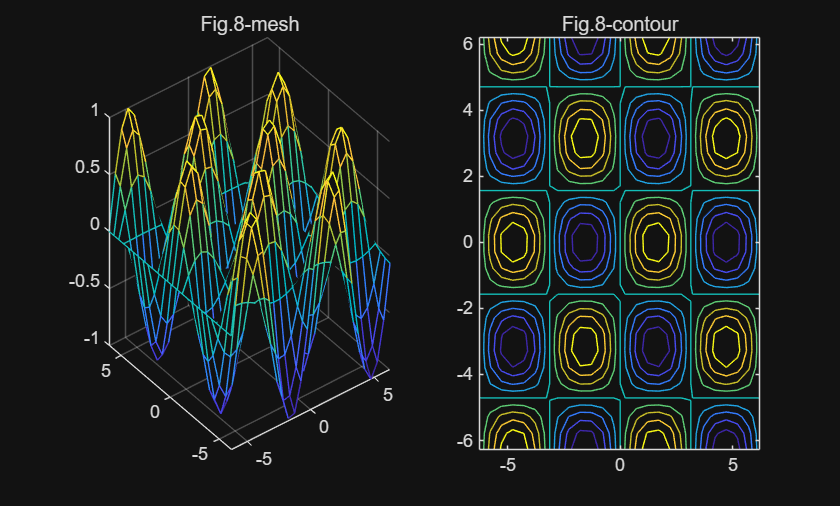

subplot(1,2,1);
mesh(x, y, z);
title("Fig.8-mesh");

subplot(1,2,2);
contour(x, y, z);
title("Fig.8-contour");

 contour()은 그래프를 등고선으로 나타내는 함수이다. 즉, 평면으로 z축의 높낮이를 보여준다.

(9)

clc; clear; clf;

t = 0:0.01:25;
y = exp(-0.15.*t).*cos(4.*t);

disp("9-9")

9-9


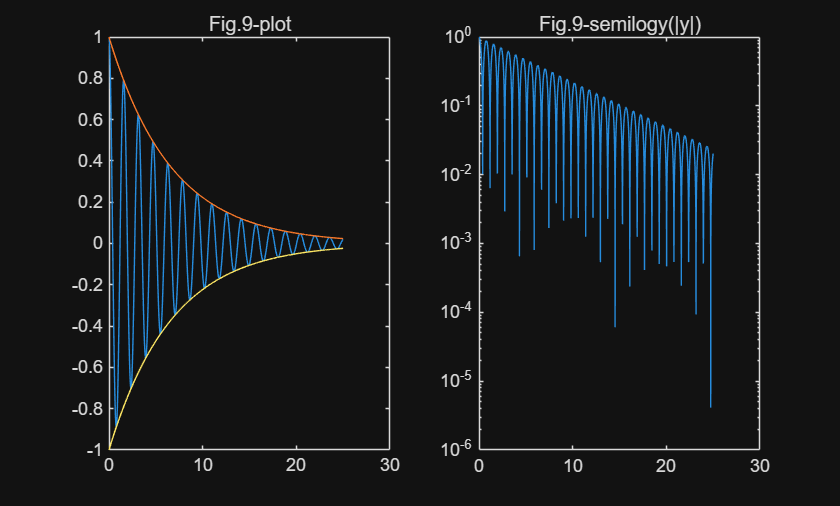

subplot(1,2,1);
plot(t,y);%(a)
hold on
plot(t, exp(-0.15.*t), t, -exp(-0.15.*t));
title("Fig.9-plot");
hold off%(b)

subplot(1,2,2);
semilogy(t,abs(y));
title("Fig.9-semilogy(|y|)")%(c)

 감쇠진동을 semilogy()를 통해 보면 최대값이 선형으로 작아지는것을 확인할 수 있다. 이는감쇠진동의 envelope가 지수함수임을 나타낸다.

(10)

clc; clear; clf;

[x, y] = meshgrid(-6:1:6);
z = cos(x).*sin(y.*exp(-0.05.*(x.^2 + y.^2)));

disp("9-10");

9-10


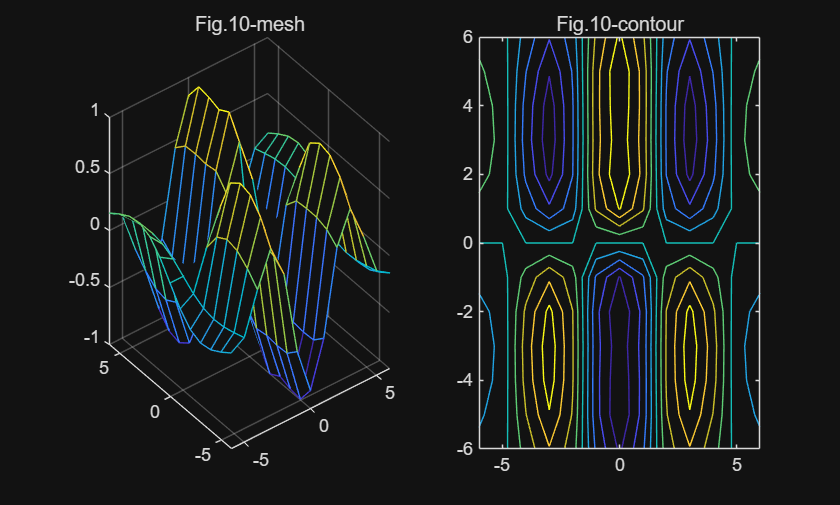

subplot(1,2,1);
mesh(x, y, z); title("Fig.10-mesh");%a

subplot(1,2,2);
contour(x, y, z);
title("Fig.10-contour");%b


zmax = max(max(z))

zmax = 0.9978

%위치 어떻게 수치적으로 추청함???

(11)

clc; clear; clf;

t = 0:1:6;
C = [12, 8.9, 6.6, 4.9, 3.6, 2.7, 2.0];

disp("9-11");

9-11


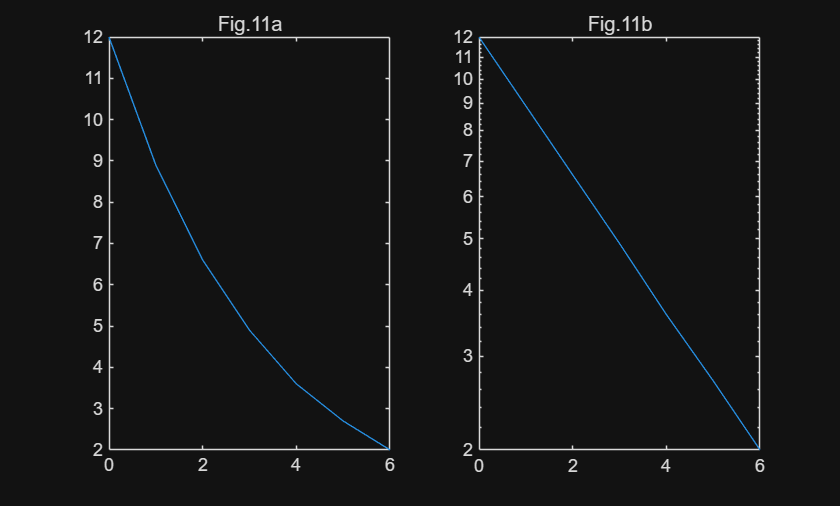

subplot(1,2,1);
plot(t, C);
title("Fig.11a");%a

subplot(1,2,2);
semilogy(t, C);
title("Fig.11b");%b


k = log(12) - log(8.9)

k = 0.2989

(12)

clc; clear; clf;

n = 1:1:30;
T1 = n;
T2 = n.*log(n);
T3 = n.^2;
T4 = 2.^n;

disp("9-12");

9-12


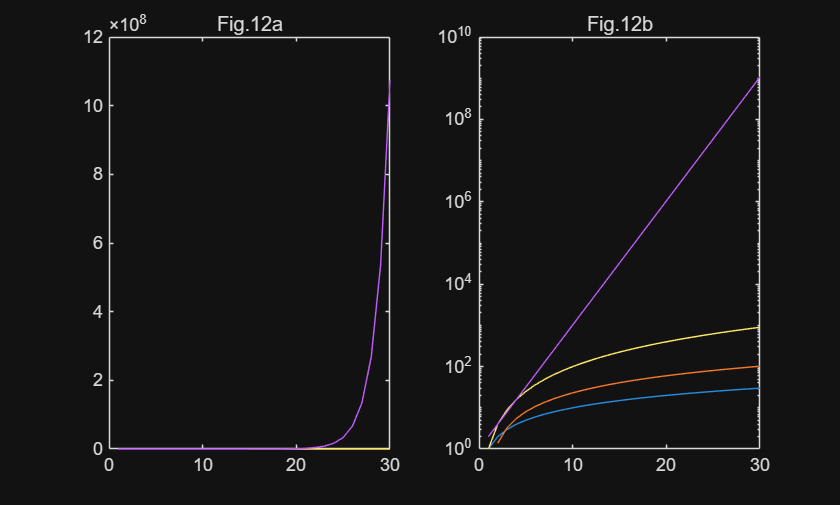

subplot(1,2,1);
plot(n,T1,n,T2,n,T3,n,T4);
title("Fig.12a");%a

subplot(1,2,2);
semilogy(n,T1,n,T2,n,T3,n,T4);
title("Fig.12b");%b

log scale가 성장률 비교에 더 적절하다. 일반 plot으로 비교하면 n값이 커짐에 따라 함수값 사이의 격차가 기하급수적으로 늘어 비교가 어려우나, log scale로 비교하면 기하급수적인 격차도 한 눈에 들어오기 때문이다.

(16)

clc; clear; clf;

t = 0:0.5:24;
T = 15 + 10.*sin(pi.*t./12);

disp("9-16");

9-16


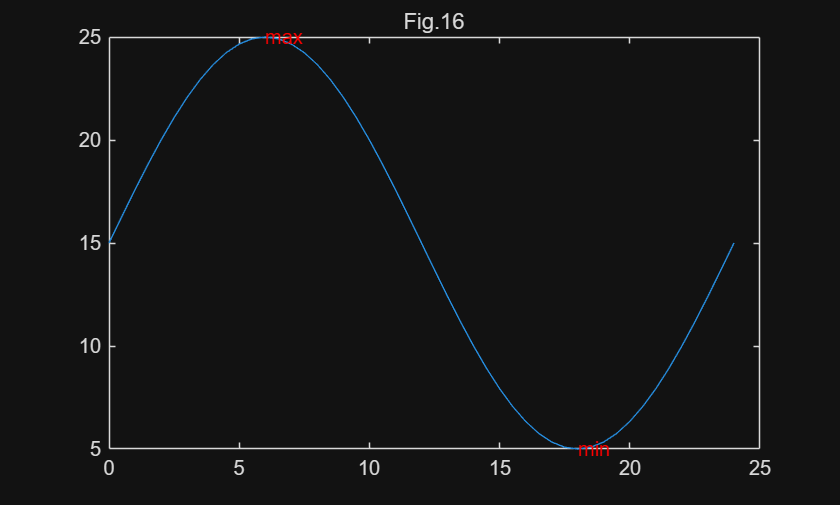

plot(t,T);
title("Fig.16");%a
hold on
text(6, 25, 'max', Color='r');
text(18,5,'min',color='r');
hold off%b

(17)

clc; clear; clf;

t = 0:1:20;
v = 5.*exp(-0.2.*t);

disp("9-17");

9-17


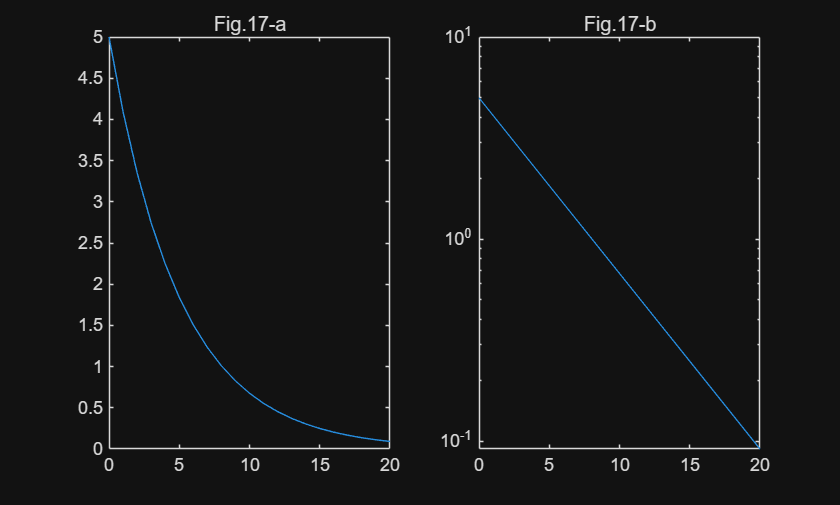

subplot(1,2,1);
plot(t,v);
title("Fig.17-a");%a

subplot(1,2,2);
semilogy(t,v);
title("Fig.17-b");%b

semilogy에서는 지수 감소가 직선으로 나타난다.

(18)

clc; clear; clf;

A = [4 -1 2;
    1 3 -1
    2 -2 5];
b = [7 4 10]';

disp("9-18");

9-18


fprintf("A² =");

A² =

disp(A^2)

    19   -11    19
     5    10    -6
    16   -18    31




fprintf("A.² =");

A.² =

disp(A.^2)%a

    16     1     4
     1     9     1
     4     4    25



% A^2는 A에 A를 행렬곱한 결과를 반환한다.
% A.^2는 A의 원소가 제곱된 결과를 반환한다.

disp("det(A) =");

det(A) =


disp(det(A));%b

    43



% (det(A) != 0)이므로 역행렬이 존재한다.

disp("inv(A)*b =");

inv(A)*b =


disp(inv(A)*b);

    1.0465
    1.7442
    2.2791



disp("A\b =");

A\b =


disp(A\b);%c

    1.0465
    1.7442
    2.2791



% (inv(A)*b == A\b) 이다.

% (d) Ax = b의 해는 A\b = [1.0465, 1.7442, 2.2791]'이다.

(19)

clc; clear;

A = [2 -1; 3 4];
B = [1 0 -2; 3 5 1];
C = [6 -3 4; 15 14 -1];

D = C-B %a

D =      5    -3     6
    12     9    -2



X = A\D %b

X =     2.9091   -0.2727    2.0000
    0.8182    2.4545   -2.0000



if (A*X + B - C == 0)
    disp("True");
else
    disp("False");
end %c

False



%d// 직접 역행렬을 구하는 inv()보다
% 가우시안소거법을 이용하는 \가
% 더 계산이 빠르기 때문이다.

(20)

clc; clear;

X = [3 7 2 5;
    5 9 4 6;
    8 12 7 10;
    10 15 9 13;
    14 18 12 16];

avg = mean(X) %a

avg =     8.0000   12.2000    6.8000   10.0000



Xc = X - avg %b

Xc =    -5.0000   -5.2000   -4.8000   -5.0000
   -3.0000   -3.2000   -2.8000   -4.0000
         0   -0.2000    0.2000         0
    2.0000    2.8000    2.2000    3.0000
    6.0000    5.8000    5.2000    6.0000



S = Xc' * Xc %c

S =    74.0000   76.0000   68.0000   79.0000
   76.0000   78.8000   70.2000   82.0000
   68.0000   70.2000   62.8000   73.0000
   79.0000   82.0000   73.0000   86.0000



%d
%대각원소: 각 변수의 분산
%비대각원소: 변수 간 공분산